syms thrust torque 

A_thrust = 0.091492681;
B_thrust = 0.067673604;
C = 0.005964552;
L = 0.046;
d = L/sqrt(2);

poly = [A_thrust, B_thrust, thrust];
r = roots(poly)*100

$$r = \left(\begin{array}{c} -\frac{3602879701896396800\,\sqrt{\frac{371550758155782996425635426969}{81129638414606681695789005144064}-\frac{6592742464939643\,\mathrm{thrust}}{18014398509481984}}}{6592742464939643}-\frac{243819854205774800}{6592742464939643}\\ \frac{3602879701896396800\,\sqrt{\frac{371550758155782996425635426969}{81129638414606681695789005144064}-\frac{6592742464939643\,\mathrm{thrust}}{18014398509481984}}}{6592742464939643}-\frac{243819854205774800}{6592742464939643} \end{array}\right)$$


mixer_matrix = [1 1 1 1;
                -d -d d d;
                d -d -d d;
                C -C C -C];





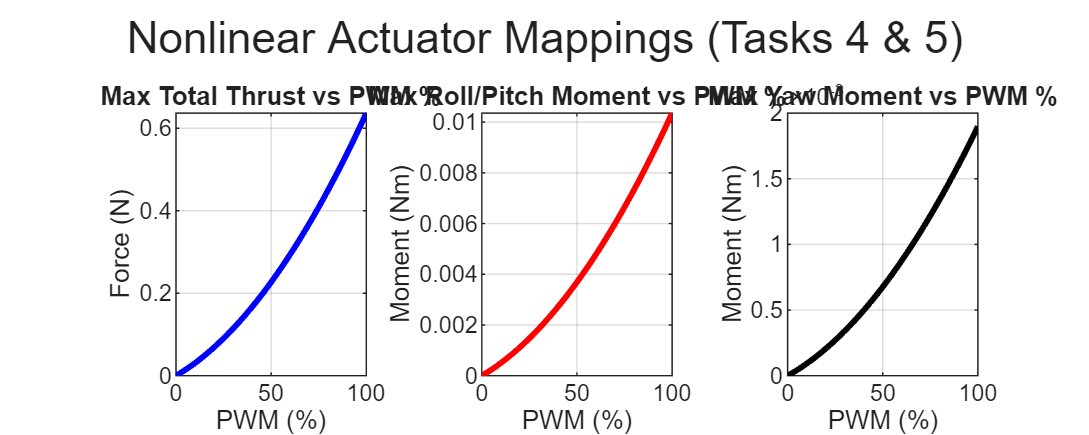

clear; clc; close all;

%% Define Quadcopter Parameters
A_thrust = 0.091492681;
B_thrust = 0.067673604;
L = 0.046;
C_tau = 0.005964552;
d = L * (sqrt(2)/2);

% Physical Force Limits per motor (Based on ratio 0.0 to 1.0)
F_min = 0;
F_max = A_thrust*(1)^2 + B_thrust*(1); 

%% Task 5: Visualize Thrust and Moments vs PWM Percentage
pwm_pct_plot = linspace(0, 100, 100);
pwm_ratio_plot = pwm_pct_plot / 100;

% Nonlinear forces
F_plot = A_thrust * (pwm_ratio_plot.^2) + B_thrust * pwm_ratio_plot;

figure('Position', [100, 100, 1000, 400]);

% Plot Total Thrust
subplot(1,3,1);
plot(pwm_pct_plot, 4 * F_plot, 'b', 'LineWidth', 2);
title('Max Total Thrust vs PWM %');
xlabel('PWM (%)'); ylabel('Force (N)'); grid on;

% Plot Roll/Pitch Moment 
subplot(1,3,2);
plot(pwm_pct_plot, 2 * d * F_plot, 'r', 'LineWidth', 2);
title('Max Roll/Pitch Moment vs PWM %');
xlabel('PWM (%)'); ylabel('Moment (Nm)'); grid on;

% Plot Yaw Moment
subplot(1,3,3);
plot(pwm_pct_plot, 2 * C_tau * F_plot, 'k', 'LineWidth', 2);
title('Max Yaw Moment vs PWM %');
xlabel('PWM (%)'); ylabel('Moment (Nm)'); grid on;

sgtitle('Nonlinear Actuator Mappings (Tasks 4 & 5)');


%% Test the Mixer (Tasks 1, 2, 3)
% Let's command hover thrust + an aggressive roll command
Fc_cmd = 0.323; % ~Hover weight
Lc_cmd = 0; % Aggressive roll
Mc_cmd = 0.8;
Nc_cmd = 0;

[pwm_outputs, F_actual] = quad_mixer(Fc_cmd, Lc_cmd, Mc_cmd, Nc_cmd, A_thrust, B_thrust, d, C_tau, F_min, F_max);

disp('--- Commanded vs Actual ---');

--- Commanded vs Actual ---


fprintf('Commanded Forces: [%.4f, %.4f, %.4f, %.4f] N\n', Fc_cmd, Lc_cmd, Mc_cmd, Nc_cmd);

Commanded Forces: [0.3230, 0.0000, 0.8000, 0.0000] N


fprintf('Required Motor PWMs (%%): [%.1f%%, %.1f%%, %.1f%%, %.1f%%]\n', pwm_outputs(1), pwm_outputs(2), pwm_outputs(3), pwm_outputs(4));

Required Motor PWMs (%): [100.0%, 0.0%, 0.0%, 100.0%]




%% The Mixer Function (Implements Inversion & Saturation Strategy)
function [pwm_pct, F_des] = quad_mixer(Fc, Lc, Mc, Nc, A, B, d, C_tau, F_min, F_max)
    
    % 1. Linear Mapping Matrix
    M_mix = [1,      1,      1,      1; 
            -d,     -d,      d,      d; 
             d,     -d,     -d,      d; 
             C_tau, -C_tau,  C_tau, -C_tau];
         
    % Calculate desired forces
    U_cmd = [Fc; Lc; Mc; Nc];
    F_des = M_mix \ U_cmd;
    
    % 2 & 3. Actuator Saturation & Infeasible Command Handling
    % Strategy: Shift forces to preserve moments, scale if impossible.
    
    if max(F_des) > F_max
        % Shift down (Sacrifice altitude to keep attitude)
        shift = max(F_des) - F_max;
        F_des = F_des - shift;
    end
    
    if min(F_des) < F_min
        % Shift up
        shift = F_min - min(F_des);
        F_des = F_des + shift;
    end
    
    % If the spread is wider than physical limits, we must scale moments down
    if (max(F_des) - min(F_des)) > (F_max - F_min)
        mid_req = mean(F_des);
        mid_phys = (F_max + F_min) / 2;
        scale = (F_max - F_min) / (max(F_des) - min(F_des));
        
        % Center and scale
        F_des = mid_phys + scale * (F_des - mid_req);
    end
    
    % Final safety clamp against floating point errors
    F_des = max(min(F_des, F_max), F_min);
    
    % 4. Nonlinear Inversion (Force to PWM Ratio)
    % Solve: A*x^2 + B*x - F_des = 0 for positive root
    pwm_ratio = (-B + sqrt(B^2 + 4*A.*F_des)) ./ (2*A);
    
    % 5. Convert to valid percentage output
    pwm_pct = pwm_ratio * 100;
end



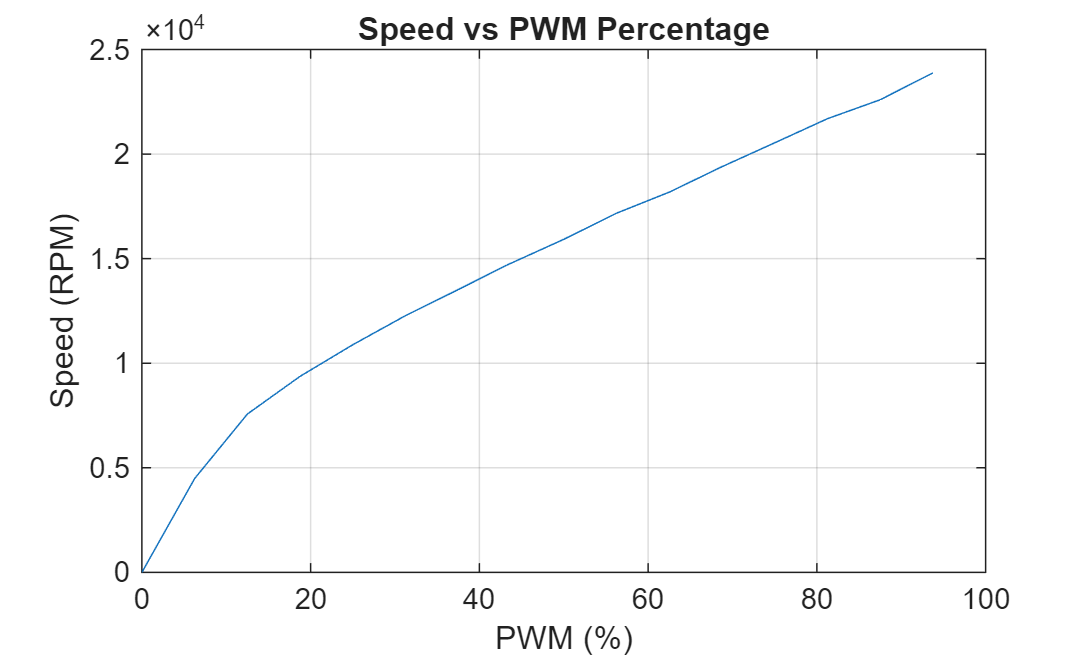


data = [0.24 0.0 4.01 0 0;
0.37 1.6 3.98 6.25 4485;
0.56 4.8 3.95 12.5 7570;
0.75 7.9 3.92 18.75 9374;
0.94 10.9 3.88 25 10885;
1.15 13.9 3.84 31.25 12277;
1.37 17.3 3.80 37.5 13522;
1.59 21.0 3.76 43.25 14691;
1.83 24.4 3.71 50 15924;
2.11 28.6 3.67 56.25 17174;
2.39 32.8 3.65 62.5 18179;
2.71 37.3 3.62 68.75 19397;
3.06 41.7 3.56 75 20539;
3.46 46.0 3.48 81.25 21692;
3.88 51.9 3.40 87.5 22598;
4.44 57.9 3.30 93.75 23882];

thrust_data = data(:,2);
pwm_data = data(:, 4);
speed_data = data(:, 5);

figure
plot(pwm_data, speed_data)
xlabel('PWM (%)');
ylabel('Speed (RPM)');
title('Speed vs PWM Percentage');
grid on;
hold on;

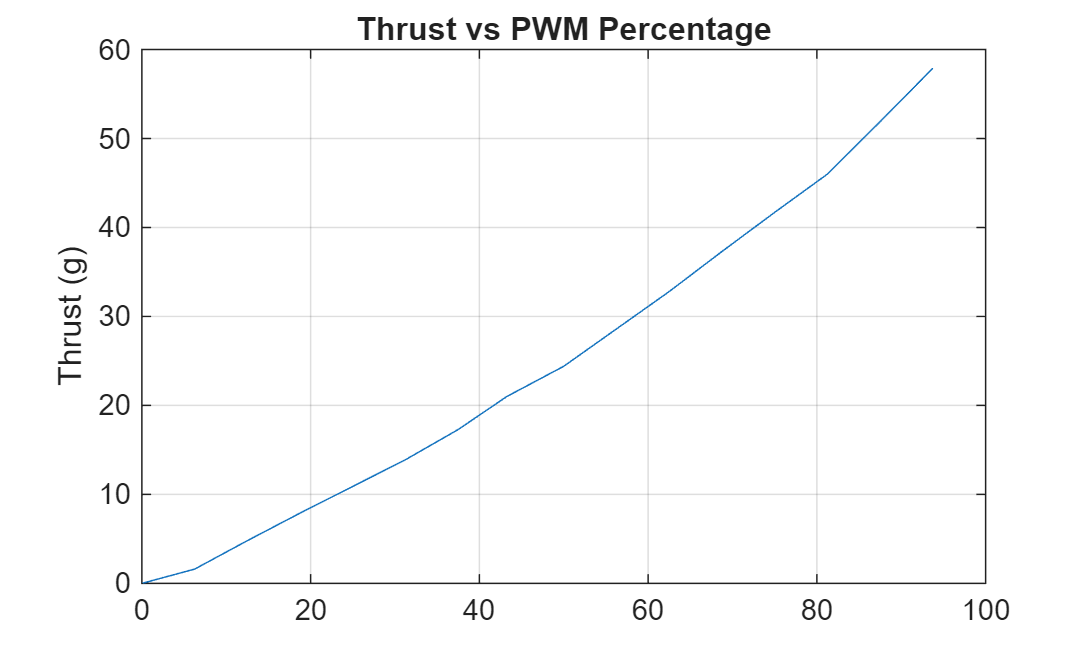



figure
plot(pwm_data, thrust_data)
ylabel('Thrust (g)');
title('Thrust vs PWM Percentage');
grid on;
hold off;


cf = fit(pwm_data, thrust_data, 'poly2')

cf =      Linear model Poly2:
     cf(x) = p1*x^2 + p2*x + p3
     Coefficients (with 95% confidence bounds):
       p1 =    0.002652  (0.002347, 0.002956)
       p2 =      0.3623  (0.3327, 0.3918)
       p3 =      -0.114  (-0.7115, 0.4834)

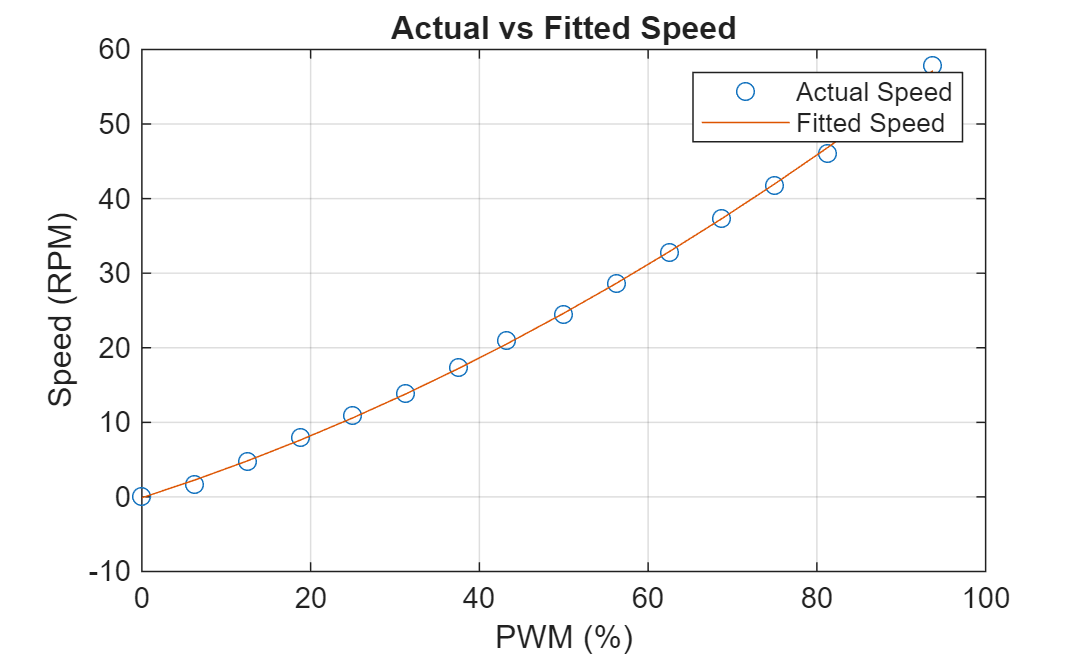

% Generate predictions using the fitted model
predicted_speed = cf(pwm_data);

% Plot the predicted speed against actual speed for comparison
figure;
plot(pwm_data, thrust_data, 'o', 'DisplayName', 'Actual Speed');
hold on;
plot(pwm_data, predicted_speed, '-', 'DisplayName', 'Fitted Speed');
xlabel('PWM (%)');
ylabel('Speed (RPM)');
title('Actual vs Fitted Speed');
legend show;
grid on;
hold off;



cf_2 = fit(pwm_data, speed_data, 'poly2')

cf_2 =      Linear model Poly2:
     cf_2(x) = p1*x^2 + p2*x + p3
     Coefficients (with 95% confidence bounds):
       p1 =      -1.434  (-2.073, -0.7948)
       p2 =       358.1  (296, 420.2)
       p3 =        2073  (818.2, 3328)

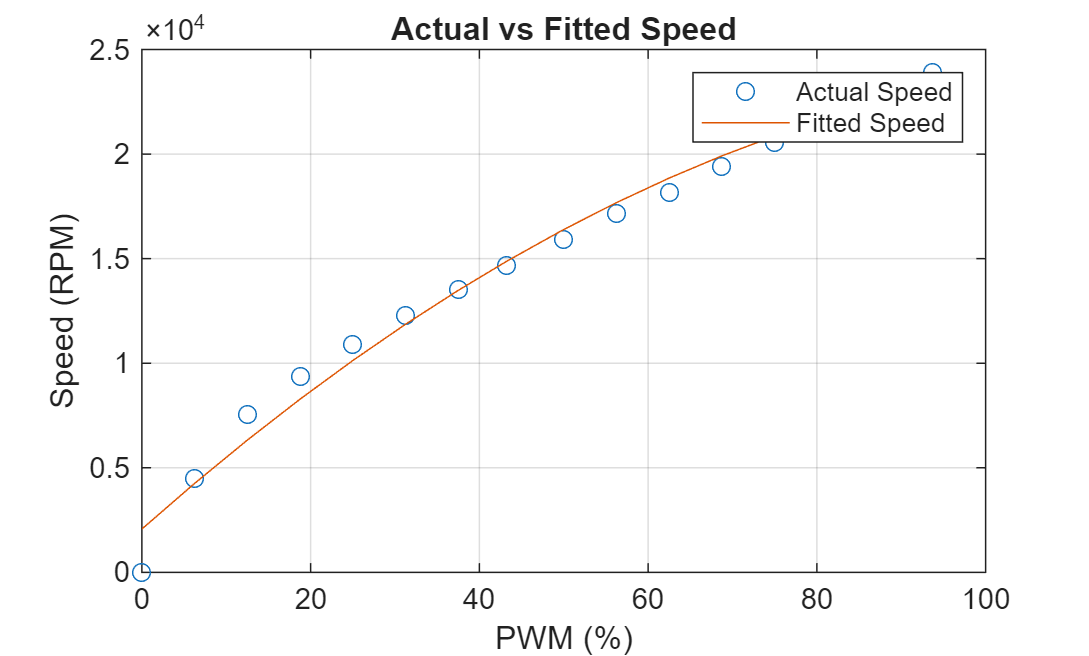


predicted_speed = cf_2(pwm_data);

% Plot the predicted speed against actual speed for comparison
figure;
plot(pwm_data, speed_data, 'o', 'DisplayName', 'Actual Speed');
hold on;
plot(pwm_data, predicted_speed, '-', 'DisplayName', 'Fitted Speed');
xlabel('PWM (%)');
ylabel('Speed (RPM)');
title('Actual vs Fitted Speed');
legend show;
grid on;
hold off;

% constant params
pwm_hover_value = 0.6408;
u0 = [pwm_hover_value; pwm_hover_value; pwm_hover_value; pwm_hover_value]; 


A_thrust = 0.091492681;
B_thrust = 0.067673604;
L = 0.046;
drone_mass_kg = 0.033;

% intertia (should some be negative)?
J = [16.571710 0.830806 0.718277;
      0.830806 16.655602 1.800197;
      0.718277 1.800197 29.261652].*10e-6;
Ts = 0.01; % SAMPLING TIME MUST CHANGE
num_d = [0.0304596];
den_d = [1 , -0.9695404];

sys_discrete = tf(num_d, den_d, Ts, 'Variable', 'z^-1');

sys_continuous = d2c(sys_discrete, 'zoh') % zero order hold 


sys_continuous =
 
  0.03046 s + 3.093
  -----------------
      s + 3.093
 
Continuous-time transfer function.



[A_act, B_act, C_act, D_act] = ssdata(sys_continuous); % continuous state space for the motor dynamics. 



%states (16now)
syms pn pe pd u v w phi theta psi p q r real
syms pwm_act_1 pwm_act_2 pwm_act_3 pwm_act_4 real
% Inputs
syms pwm_cmd_1 pwm_cmd_2 pwm_cmd_3 pwm_cmd_4 real

state_vector_2 = [pn; pe; pd; u; v; w; phi; theta; psi; p; q; r; pwm_act_1; pwm_act_2; pwm_act_3; pwm_act_4];
input_vector_2 = [pwm_cmd_1; pwm_cmd_2; pwm_cmd_3; pwm_cmd_4];




% forces
F1 = A_thrust * pwm_act_1^2 + B_thrust*pwm_act_1;
F2 = A_thrust * pwm_act_2^2 + B_thrust*pwm_act_2;
F3 = A_thrust * pwm_act_3^2 + B_thrust*pwm_act_3;
F4 = A_thrust * pwm_act_4^2 + B_thrust*pwm_act_4;
F_total_body = [0; 0; -(F1 + F2 + F3 + F4)]; % total force in body frame NED

%motor torques
T1 = 0.005964552 * F1;
T2 = 0.005964552 * F2;
T3 = 0.005964552 * F3;
T4 = 0.005964552 * F4;

% motor dynamics
pwm_act1_dot = A_act * pwm_act_1 + B_act * pwm_cmd_1;
pwm_act2_dot = A_act * pwm_act_2 + B_act * pwm_cmd_2;
pwm_act3_dot = A_act * pwm_act_3 + B_act * pwm_cmd_3;
pwm_act4_dot = A_act * pwm_act_4 + B_act * pwm_cmd_4;

% moment vector torques
l = L*(sqrt(2)/2)*(F3 + F4 - F1 - F2);
m = L*(sqrt(2)/2)*(F1 + F4 - F3 - F2);
n = T1 + T3 - T2 - T4;
moments = [l; m; n];




% all rotations 
Rx = [1 0 0; 
    0 cos(phi) -sin(phi); 
    0 sin(phi) cos(phi)];

Ry = [cos(theta) 0 sin(theta); 
    0 1 0; 
    -sin(theta) 0 cos(theta)];

Rz = [cos(psi) -sin(psi) 0; 
       sin(psi) cos(psi) 0; 
       0 0 1];

R_body_to_inertial = Rz * Ry * Rx; % rotation Matrix (Body to Inertial - ZYX Sequence)


p_dot = R_body_to_inertial * [u; v; w]; % p_dot states 1-3



W = [1, sin(phi)*tan(theta), cos(phi)*tan(theta);
     0, cos(phi),            -sin(phi);
     0, sin(phi)/cos(theta), cos(phi)/cos(theta)];
euler_dot = W * [p; q; r]; % angular dynamics states 7-9

% Gravity rotated to Body Frame
g_inertial = [0; 0; 9.81]; 
g_body = R_body_to_inertial' * g_inertial;

omega = [p; q; r];
v_body = [u; v; w];


% aroo dynamics 
K_aeroo = [-10.2506 -0.3177 -0.4332;
-0.3177 -10.2506 -0.4332;
-7.7050 -7.7050 -7.5530].*10e-7;

% these in rev/s
n1 = (2073 + pwm_act_1*358.1 - 1.434*(pwm_act_1^2))/60;
n2 = (2073 + pwm_act_2*358.1 - 1.434*(pwm_act_2^2))/60;
n3 = (2073 + pwm_act_3*358.1 - 1.434*(pwm_act_3^2))/60;
n4 = (2073 + pwm_act_4*358.1 - 1.434*(pwm_act_4^2))/60;

theta_dot_sigma = 2*pi*(abs(n1) + abs(n2) + abs(n3) + abs(n4));

f_aeroo = K_aeroo * theta_dot_sigma * (R_body_to_inertial*v_body);

v_dot = (1/drone_mass_kg) * (F_total_body + f_aeroo + drone_mass_kg*g_body) - cross(omega, v_body); % dynamics for states 4-6


omega_dot = inv(J) * (moments - cross(omega, J * omega)); % rigid body calc


f_x_2 = [p_dot; 
       v_dot; 
       euler_dot; 
       omega_dot; 
       pwm_act1_dot; 
       pwm_act2_dot; 
       pwm_act3_dot; 
       pwm_act4_dot];



## Linearizing the 16-state model. 


% linearize
A_sym_2 = jacobian(f_x_2, state_vector_2);
B_sym_2 = jacobian(f_x_2, input_vector_2);

% hover state and hover inputs
x0_2 = zeros(16, 1);      
x0_2(13:16) = pwm_hover_value;
u0_2 = [pwm_hover_value; pwm_hover_value; pwm_hover_value; pwm_hover_value];

% substitute into linearized system
A_2 = double(subs(A_sym_2, [state_vector_2; input_vector_2], [x0_2; u0_2]))

A_2 =          0         0         0    1.0000         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0    1.0000         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0    1.0000         0         0         0         0         0         0         0         0         0         0
         0         0         0   -0.2995   -0.0093   -0.0127         0   -9.8100         0         0         0         0         0         0         0         0
         0         0         0   -0.0093   -0.2995   -0.0127    9.8100         0         0         0         0         0         0         0         0         0
         0         0         0   -0.2251   -0.2251   -0.2207         0         0         0         0         0         0   -5.6040   -5.6040   -5.6040   -5.6040
         0         0        

B_2 = double(subs(B_sym_2, [state_vector_2; input_vector_2], [x0_2; u0_2]))

B_2 =      0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0
     2     0     0     0
     0     2     0     0
     0     0     2     0



% start making C and D, which will do a bunch of conversion stuff. 
r2d = 180/pi;

C_2 = zeros(16, 16);

% Positions \
C_2(1, 2) = 1;  
C_2(2, 1) = 1;   
C_2(3, 3) = -1;  

% Velocities 
C_2(4, 5) = 1;   
C_2(5, 4) = 1;   
C_2(6, 6) = -1;  

% Euler Angles (NED Rads -> ENU Degrees)
C_2(7, 8) = r2d;   
C_2(8, 7) = r2d;   
C_2(9, 9) = -r2d;  

% Angular Rates 
% negating state 11 again. 
C_2(10, 11) = r2d;   
C_2(11, 10) = -r2d;  
C_2(12, 12) = -r2d;  

% Motor dynamics
C_2(13, 13) = C_act;
C_2(14, 14) = C_act;
C_2(15, 15) = C_act;
C_2(16, 16) = C_act

C_2 =          0    1.0000         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    1.0000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0   -1.0000         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0    1.0000         0         0         0         0         0         0         0         0         0         0         0
         0         0         0    1.0000         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0   -1.0000         0         0         0         0         0         0         0         0         0         0
         0         0        


% D Matrix is zeros except for the dynamics of the motors:
D_2 = zeros(16, 4);
D_2(13, 1) = D_act;
D_2(14, 2) = D_act;
D_2(15, 3) = D_act;
D_2(16, 4) = D_act

D_2 =          0         0         0         0
         0         0         0         0
         0         0         0         0
         0         0         0         0
         0         0         0         0
         0         0         0         0
         0         0         0         0
         0         0         0         0
         0         0         0         0
         0         0         0         0
         0         0         0         0
         0         0         0         0
    0.0305         0         0         0
         0    0.0305         0         0
         0         0    0.0305         0


## Step input for the 16-state model

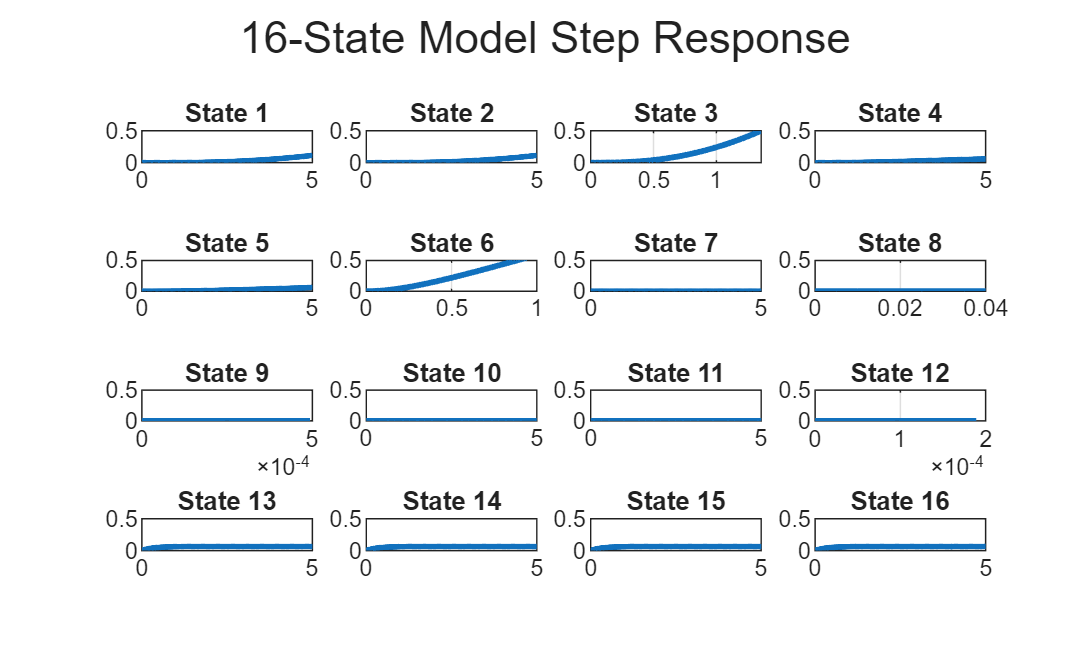

sys_sim = ss(A_2, B_2, C_2, D_2);

% 10% increase from hover
u_step = u0 * 1.1; 


U_delta = (u_step - u0)'; 

t = 0:0.01:5;  % using the same sampling period .01s 
U = repmat(U_delta, length(t), 1); 

[y, tOut] = lsim(sys_sim, U, t);


for i = 1:16
    subplot(4, 4, i);
    plot(tOut, y(:,i), 'LineWidth', 2);
    ylim([0 0.5]);
    title(['State ' num2str(i)]);
    grid on;
end
sgtitle('16-State Model Step Response');